## TOPIC 23: Differential equation solvers and other numerical methods

ENGR105, 11/19/20

### Solving ordinary differential equations (ODEs)

ODEs desribe a relationship between derivatives with respect to a single variable. For example, a common **first order ODE** relates the time derivative of a function, $\frac{d}{\mathrm{d}t}x\left(t\right)$, to the function itself, $x\left(t\right)$, and the independent variable:

            
$$\frac{d}{\mathrm{d}t}x\left(t\right)=f\left(t,x\left(t\right)\right)$$


The **order** of an ODE is the highest order derivative. **Higher-order ODEs** relate higher-order derivatives to lower order derivatives, the dependent variable / function, and the independent variable.

            
$$\frac{d^2 }{\mathrm{d}t^2 }x\left(t\right)=f\left(t,x\left(t\right),\frac{d}{\mathrm{d}t}x\left(t\right)\right)$$


**Remember**: to solve an ODE, the number of initial conditions must be same as the order.

Systems of ordinary differential equations  appear in many engineering and science disciplines:

- Robotics and systems control

- Weather systems

- Population growth, logistics, and radioactive decay

- Dynamics of physical and electronic systems

- Many more ...

For **simple cases**, ODEs can be solved analytically by direct integration.

- Example 1

            
$$\frac{d}{\mathrm{d}t}x\left(t\right)=3t^2 +4t+\sin \left(t\right)$$


            
$$x\left(t\right)=t^3 +2t^2 -\cos \left(t\right)+c_1$$


- Example 2

            
$$\frac{d}{\mathrm{d}t}x\left(t\right)=k\;x\left(t\right)$$


            
$$x\left(t\right)=c_2 \;e^{\;\textrm{kt}}$$


However, many (if not most) ODEs can be solved more easily using a **numerical algorithm**.

#### Taylor series approximations

An underrated and extremely useful approximation for engineers involves the Taylor series representation of a function.  A **one-dimensional** Taylor series is an expansion of a real function about a point **a** given by:

        
$$f\left(x\right)={f\left(x\right)\left|\right.}_a \;+{\;\frac{\textrm{df}}{\textrm{dx}}\left|\right.}_a \left(x-a\right)\;+{\;\frac{1}{2!}\frac{d^2 f}{{\textrm{dx}}^2 }\left|\right.}_a {\left(x-a\right)}^2 +{\;\frac{1}{3!}\frac{d^3 f}{{\textrm{dx}}^3 }\left|\right.}_a {\left(x-a\right)}^3 \;+\;O\left(x^4 \right)$$


This is **extremely useful** because it allows us to represent an arbitrary function in terms of an infinite polynomial. In many cases (especially in engineering), we **approximate** a function by only considering the **first order term** in the Taylor series expansion:

        
$$f\left(x\right)\approx {f\left(x\right)\left|\right.}_a \;+{\;\frac{\textrm{df}}{\textrm{dx}}\left|\right.}_a \left(x-a\right)\;$$


**Example**. Compare the first, second, and third order approximations of$f\left(x\right)=\ln \left(x\right)$ at x = 1

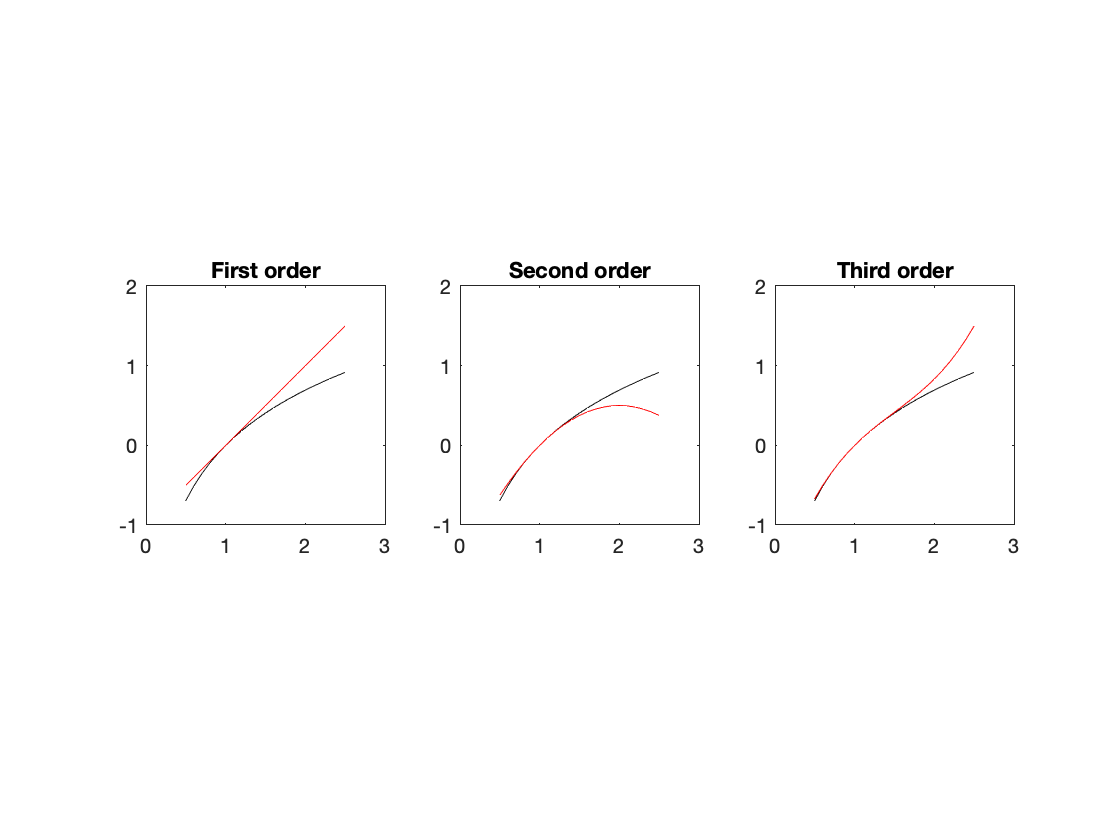

% x range of interest
x = 0.5:0.1:2.5;
% Actual function
f = log(x);

% Taylor series approximations
f_ts1 = x-1;
f_ts2 = x-1 - 1/2*(x-1).^2;
f_ts3 = x-1 - 1/2*(x-1).^2 + 1/3*(x-1).^3;


subplot(1,3,1)
plot(x,f,'k-',x,f_ts1,'r-')
axis square
ylim([-1,2])
title('First order')
subplot(1,3,2)
plot(x,log(x),'k-',x,f_ts2,'r-')
axis square
ylim([-1,2])
title('Second order')
subplot(1,3,3)
plot(x,log(x),'k-',x,f_ts3,'r-')
axis square
ylim([-1,2])
title('Third order')

**Takeaway: **the **more terms **that are included, the *better* the approximation will be.

#### Euler method: simple approximation of an ODE solution

Consider first order differential equation:

            
$$\frac{d}{\mathrm{d}t}x\left(t\right)=f\left(t,x\left(t\right)\right)$$


The solution to this ODE is $x\left(t\right)$. By performing a Taylor series expansion about $t$, we can approximate the value of the solution after some time interval:

            
$$\begin{array}{l}
x\left(t+\Delta t\right)\approx x\left(t\right)+{\;\frac{\textrm{dx}}{\textrm{dt}}\left|\right.}_t \left(\left(t+\Delta t\right)-t\right)\;\\
x\left(t+\Delta t\right)\approx x\left(t\right)+f\Delta t
\end{array}$$


This representation is known as **Euler's method**. It provides a first-order approximation for the next state of the system and **an approximate solution** can be created by **numerically** calculating the "next" point. As can be seen above, the **accuracy** of this approach is strongly determined by the **size of the time step**, $\Delta t$.

**Example**. Consider the following differential equation. Use the **Euler method** to find a numerical solution.

            $\frac{d}{\mathrm{d}t}x\left(t\right)=x-t^2 +1$, where $x\left(0\right)=0$

This can be solved using an *analytical technique* (*e.g.* with a Laplace Transform) to produce the solution:

            
$$x\left(t\right)=1-e^t +t^2 +2t$$


*Applying the Euler method:*

close all
% Time vector
t = 0:0.1:3;

% The function representing the RHS of the differential equation. This is
% defined by the problem
f = @(T,X) X-T^2+1;

% Analytical solution
x_an = (1-exp(t))+t.^2+2*t;


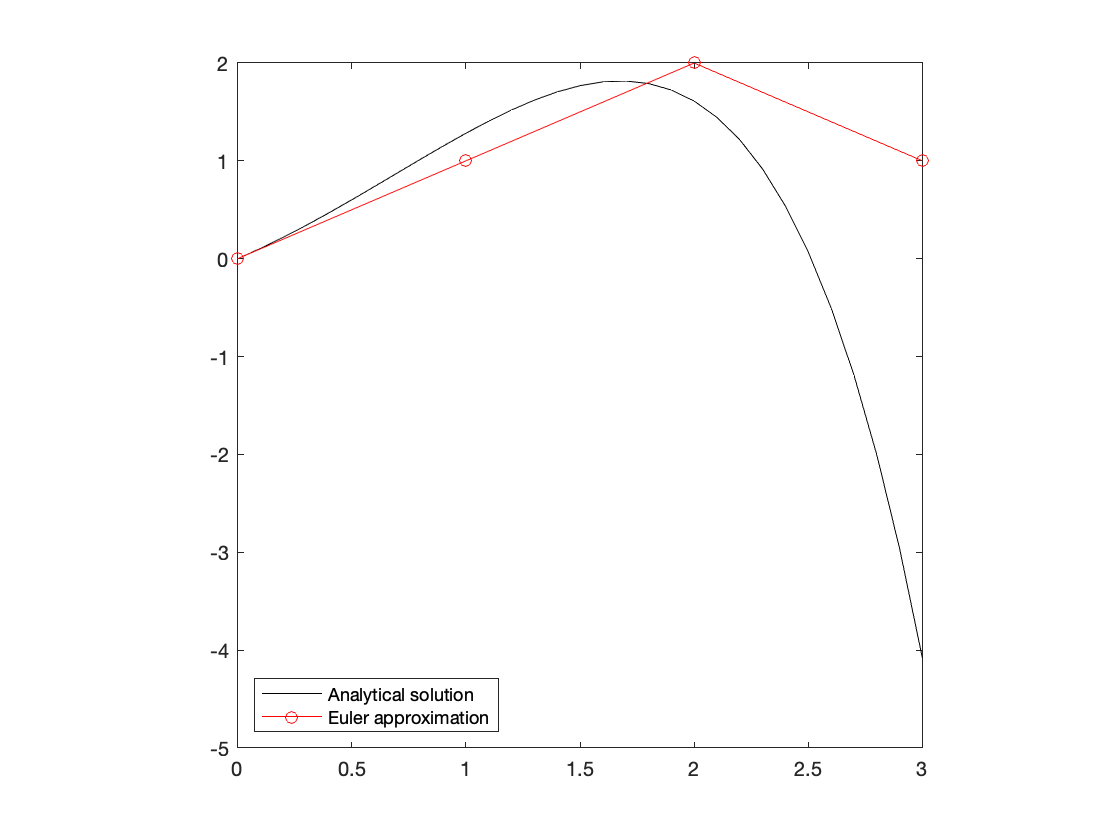

% Use Euler method
% Define the time step
dt = 1;

% Preallocate vector to store
t_approx = 0:dt:3;
x_euler = zeros(size(t_approx));

% Calculate each entry in the Euler approximation
for k = 1:length(x_euler)-1
    % Apply the Euler method
    % Calculate the next value of the solution
    x_euler(k+1) = x_euler(k) + f(t_approx(k),x_euler(k))*dt;
end

% Plot the solution
plot(t,x_an,'k-',t_approx,x_euler,'ro-')
axis square
legend('Analytical solution','Euler approximation','location','southwest')

**Note**: there is a tradeoff between accuracy and computational cost.

#### Predictor-corrector method: better approximation of a solution

A better approximation than Euler can be achieved using the predictor-corrector method. Here, consider again:

            
$$\frac{d}{\mathrm{d}t}x\left(t\right)=f\left(t,x\left(t\right)\right)$$


If we include some more *higher order terms in the Taylor Series approximation*, we would expect to achieve a better approximation. The predictor-corrector method does that, effectively estimating the derivative at the beginning ($k_1$) and end ($k_2$) of an interval

            
$$\begin{array}{l}
x\left(t+\Delta t\right)\approx x\left(t\right)+\frac{1}{2}\left(f\left(t,x\left(t\right)\right)+f\left(t+\Delta t,x\left(t\right)+f\left(\left.t,x\left(t\right)\right)\Delta t\right)\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\approx x\left(t\right)+\frac{1}{2}\left(k_1 +k_2 \right)\Delta t\\
k_1 =f\left(t,x\left(t\right)\right)\\
k_2 =f\left(t+\Delta t,x\left(t\right)+k_1 \Delta t\right)
\end{array}$$


*Applying predictor-corrector and comparing to the above:*

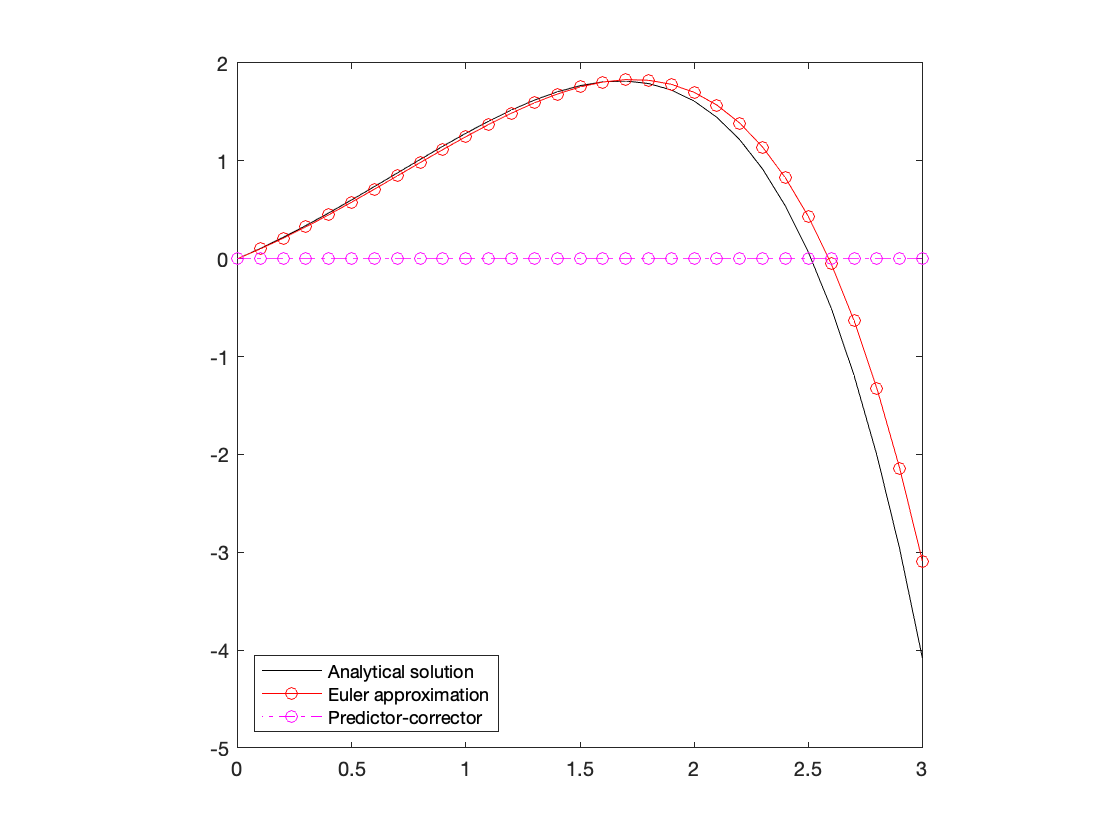

close all
% Define the time step
dt = 0.1;

% Preallocate vectors to store
t_approx = 0:dt:3;               % Time vector for all
x_euler = zeros(size(t_approx)); % Euler
x_pc = zeros(size(t_approx));    % Predictor corrector

% Calculate each entry in the Euler approximation
for m = 1:length(x_euler)-1
    % Use Euler method
    % Calculate the next value of the solution
    x_euler(m+1) = x_euler(m) + f(t_approx(m),x_euler(m))*dt;
    
    % Use predictor-corrector method
    k1 = f(t_approx(m),x_pc(m));
    k2 = f(t_approx(m)+dt,x_pc(m)+k1*dt);
    
end

% Plot the solutions
plot(t,x_an,'k-', ...
    t_approx,x_euler,'ro-',...
    t_approx,x_pc,'mo-.')
axis square
legend('Analytical solution','Euler approximation','Predictor-corrector',...
    'location','southwest')

#### Runge-Kutta solutions to differential equations

Including even more terms, the **Runge-Kutta** method provides a better approximation than predictor-corrector. Runge-Kutta can also be thought of as "following the *logic of the predictor-corrector method,*" where the accuracy of the estimate can be improved by evaluating the derivative at *multiple points* along an interval.

            
$$\begin{array}{l}
x\left(t+\Delta t\right)\approx x\left(t\right)+\frac{1}{6}\left(k_1 +{2k}_2 +{2k}_3 +k_4 \right)\Delta t\\
k_1 =f\left(t,x\left(t\right)\right)\\
k_2 =f\left(t+\frac{\Delta t}{2},x\left(t\right)+k_1 \frac{\Delta t}{2}\right)\\
k_3 =f\left(t+\frac{\Delta t}{2},x\left(t\right)+k_2 \frac{\Delta t}{2}\right)\\
k_4 =f\left(t+\Delta t,x\left(t\right)+k_3 \Delta t\right)
\end{array}$$


Here, $k_1$ corresponds to the derivative at the beginning of the interval, $k_2$ and $k_3$ are two estimates for the derivative at the midpoint of the interval, and $k_4$ is an estimate of the derivative at the end of the interval.

The above is a **Runge-Kutta approximation of rank 4** (RK4).

*Applying Runge-Kutta and comparing to the above:*

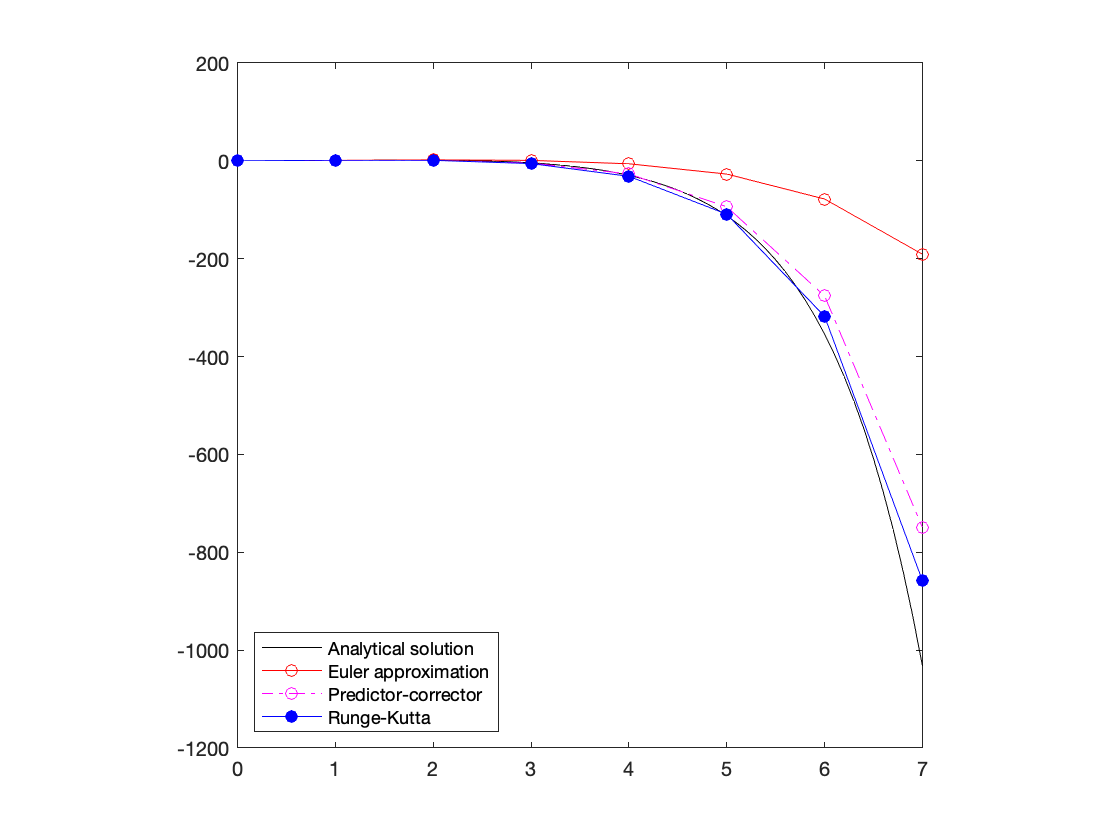

close all

% Time vector
t = 0:0.1:7;
% Analytical solution
x_an = (1-exp(t))+t.^2+2*t;

% Define the time step
dt = 1;

% Preallocate vectors to store
t_approx = 0:dt:7;               % Time vector for all
x_euler = zeros(size(t_approx)); % Euler
x_pc = zeros(size(t_approx));    % Predictor corrector
x_rk = zeros(size(t_approx));   % Runge-Kutta

% Calculate each entry in the Euler approximation
for m = 1:length(x_euler)-1
    % Use Euler method
    % Calculate the next value of the solution
    x_euler(m+1) = x_euler(m) + f(t_approx(m),x_euler(m))*dt;
    
    % Use predictor-corrector method
    k1 = f(t_approx(m),x_pc(m));
    k2 = f(t_approx(m)+dt,x_pc(m)+k1*dt);
    x_pc(m+1) = x_pc(m) + 1/2*(k1+k2)*dt;
    
    % Use Runge-Kutta method
    K1 = f(t_approx(m),x_pc(m));
    K2 = f(t_approx(m)+dt/2,x_pc(m)+K1*dt/2);
    K3 = f(t_approx(m)+dt/2,x_pc(m)+K2*dt/2);
    K4 = f(t_approx(m)+dt,x_pc(m)+K3*dt);
    x_rk(m+1) = x_rk(m) + 1/6*(K1 + 2*K2 + 2*K3 +K4)*dt;
    
end

% Plot the solutions
plot(t,x_an,'k-', ...
    t_approx,x_euler,'ro-',...
    t_approx,x_pc,'mo-.')
hold on
plot(t_approx,x_rk,'bo-','MarkerFaceColor','b')
hold off
axis square
legend('Analytical solution','Euler approximation','Predictor-corrector',...
    'Runge-Kutta','location','southwest')

**Runge-Kutta ODE solvers of RK23 and RK45** are most often used in MATLAB and can be accessed with the commands `ode23()` and `ode45()`

**Note**: How do we ever know when we have the ‘right’ numerical solution? We don’t - the best we can do is increase the accuracy of the numerical method until no further wild changes occur over the interval of interest.

Like in the previous examples, we would decrease the time step and/or increase the solution accuracy (`'``AbsTol``'` and `'``RelTol``'`) to achieve to see when the solution settles

#### Differential equation solvers in MATLAB

MATLAB offers a wide array of differential equation solvers - each has their own application set or unique “personality.” The two most popular, `ode23()` and `ode45()` are based on the **Runge-Kutta** algorithm (with *additional* numerical details as well).

**Note**: `ode45()` should be your default ODE solver for most applications.

Like our previous numerical methods, these built-in functions require an input function containing the differential equation to be solved for.

**Revisiting Newton-Raphson.** Consider our numerical root-finding algorithm that we created in Topic 12. This function takes an input function (`F`), an initial guess (`xn`), and a user defined tolerance (`tol`) that determines how long the iterative method should be repeated. *The input function is repeatedly evaluated during the iterative process.*

An example input function:

Our function would be called as:

In the above case, the solver function repeatedly interacts with the equation function during the "solving process." `ode45` requires similar formatting - namely representation of the differential equations in state space and the use of function handles

- `outputs ([t, out]): `time and corresponding position(s), velocity, etc.

- `function`: handle to function containing the description of the ODE

- `domain`: the analysis time, a 1x2 row vector `[t_min,t_max]`

- `initial conditions`: initial position(s), velocity, etc. - a 1 x n row vector depending on how many ODEs are being solved.

- `options`: user specified accuracy, resolution, etc.

- `parameters/constraints`: constants used during the evaluation of the ODE

**Example**. Consider the example above

            $\frac{d}{\mathrm{d}t}x\left(t\right)=x-t^2 +1$, where $x\left(0\right)=0$

This ODE can be stored in the following function to be used with `ode45`

*Notes:*

- Analagously to Newton-Raphson, the numerically-solved differential function is stored as its **own MATLAB function**

- It is important that a variable representing **time** **appears as the first input** to the ODE function even if not *explicitly* referenced in the ODE function

*Solving the ODE:*

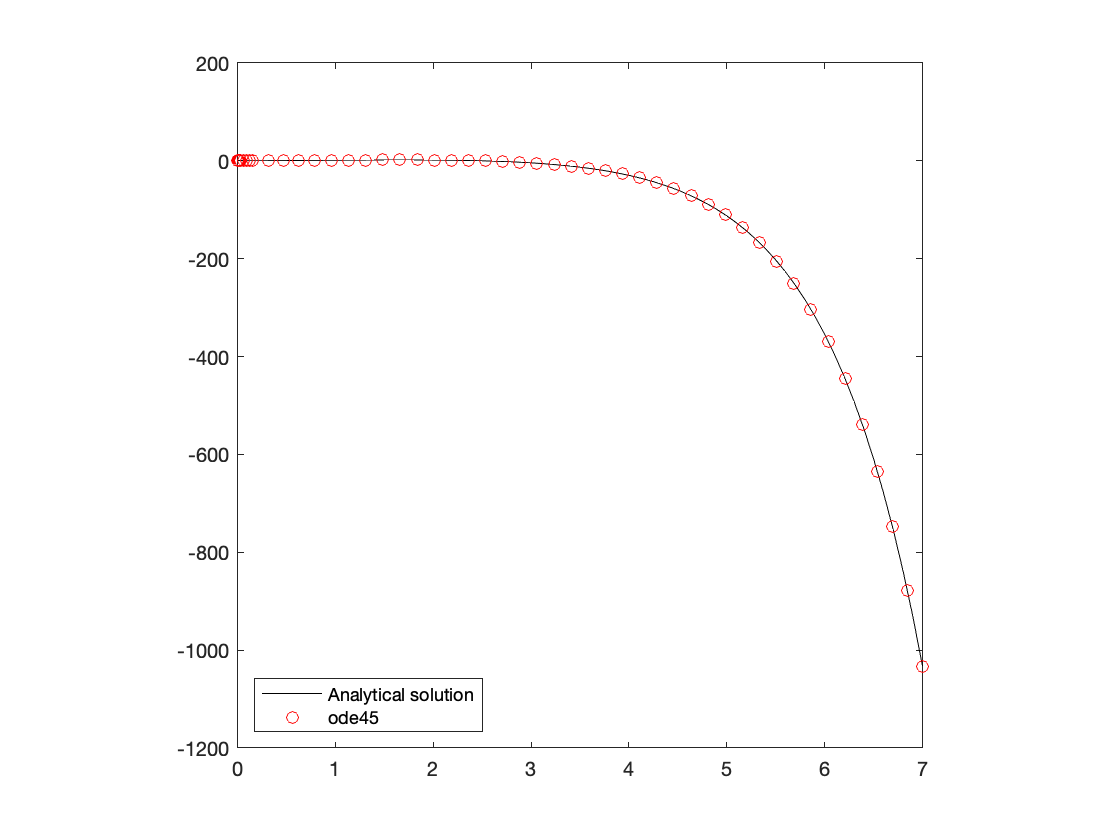

close all
% Solve ODE using ode45
[ts,xs] = ode45(@myODE,[0,7],[0]);

% Compare to analytical solution
plot(t,x_an,'k-',ts,xs,'ro')
axis square
legend('Analytical solution','ode45','location','southwest')

*Notes:*

- `ode45` requires inputs of time and initial conditions, and returns a vector or matrix of solutions to the differential equation

- Instead of input start and end points of a time domain, you can also **enter a vector of time points to evaluate the function at**.

#### Example: chemical reaction kinetics

Consider an arbitrary set of chemical reactions.

            
$$\begin{array}{l}
A\iff_{k_{1,r} }^{k_{1,f} } B\\
B\iff_{k_{2,r} }^{k_{2,f} } C
\end{array}$$


**Queston.** If 1 mol of A is initially present, how does the composition of the system evolve over time? In this case, assume the reaction has following rate constants: $k_{1,f} =1\;s^{-1}$, $k_{1,r} =2\;s^{-1}$,$k_{2,f} =2\;s^{-1}$,$k_{2,r} =0\ldotp 5\;s^{-1}$

First observation: we are dealing with a **set of differential equations**. Applying our knowledge of chemistry and substituting in the rate constants produces the following system of differential equations:

            
$$\begin{array}{l}
\frac{\textrm{dA}}{\textrm{dt}}\;=-A+2B\\
\frac{\textrm{dB}}{\textrm{dt}}\;=A-2B+0\ldotp 5C-2B=A-4B+0\ldotp 5C\\
\frac{\textrm{dC}}{\textrm{dt}}=2B-0\ldotp 5C\;
\end{array}$$


This set of differential equations can be encapsulated into a function. In this case, there a multiple inputs and multiple outputs. Each input corresponds to the amount of one chemical, and each output coresponds to the differential equation relating the change of that variable.

**Note**: the derivatives have to be returned as a **column vector**

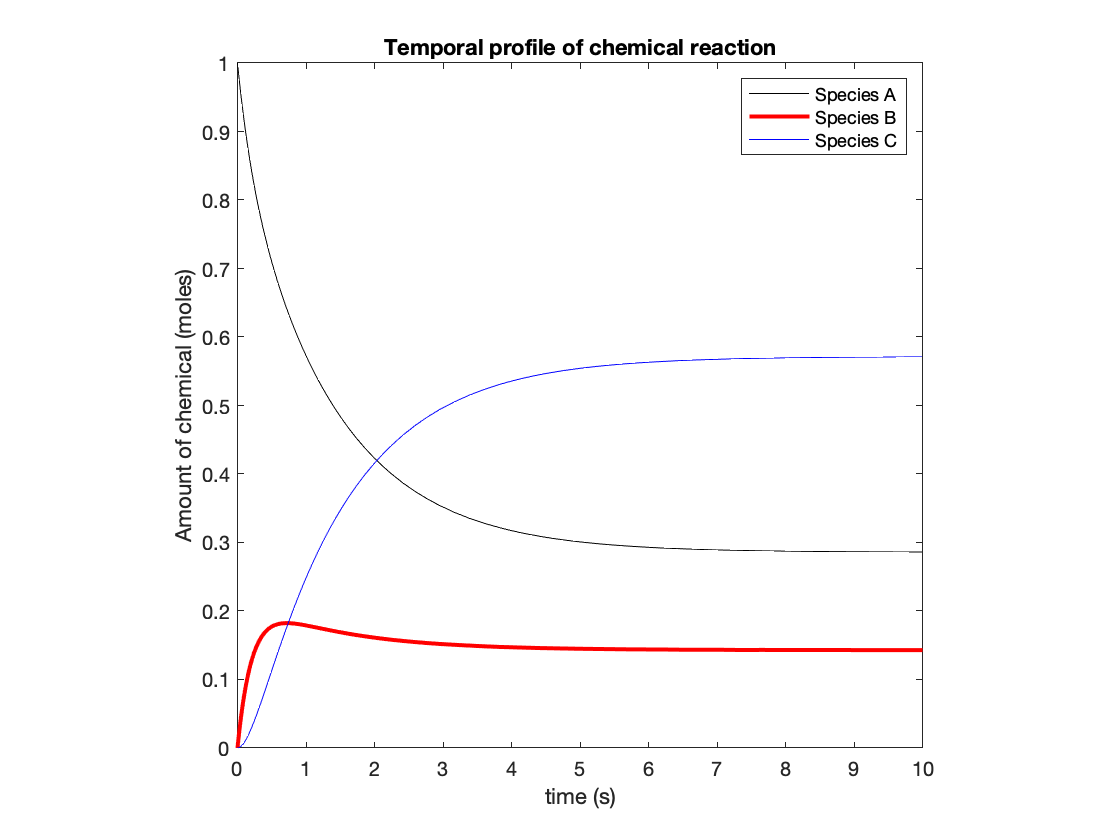

close all
% Solve ODE using ode45
[t,moles] = ode45(@rxnEqns,[0,10],[1,0,0]);

% Plot time-dependent profiles
plot(t,moles(:,1),'k-')
hold on
plot(t,moles(:,2),'r-','LineWidth',2)
plot(t,moles(:,3),'b-')
hold off

% Graphical parameters
axis square
legend('Species A','Species B','Species C','location','northeast')
ylim([0,1])
ylabel('Amount of chemical (moles)')
xlabel('time (s)')
title('Temporal profile of chemical reaction')

#### ODEs of higher orders 

The previous example was a system of **first order** ODEs. To solve a higher order ODE using `ode45`, we need to convert it to a **system of first order ODEs**. 

**Example: formulating a system of first order ODEs from a third-order linear ODE. **Say we have an equation of the form:

            

This would be input into MATLAB as a series of differential equations of first order using the following method. 

- Define a new variable

- Rearrange the ODE so that the highest order derivative is on the left hand side of the equation and all other terms are on the right hand side of the equation

- Rewrite the ODE from (2) substituting in the generalized variables

- Relate the lower order derivatives to the higher order derivatives

1) We start by assigning generalized variables (say *x*) to derivatives of *y* of increasing order as such

            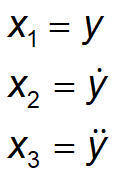

2) Next, we **rearrange the ODE** to get the derivative of highest order on the left side of the equation

            

3) Now, we **substitute the new variables** into the ODE

            

4) Finally, we establish relationships between lower order derivatives and non-differentiated terms

            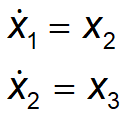

***Summary***. The original third-order ODE was:

            

And has been converted to the following set of linear first-order ODEs for input into a MATLAB ODE solver

            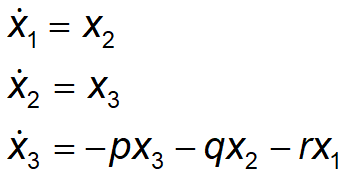

**MATLAB implementation**.

When it is in the correct format (system of differential equations), the set of equations can then be input into a function definition of the ODE for use in MATLAB.

*Notes:*

- As before, time and x values serve as inputs

- As before, derivatives of the generalized variables have to be returned as a **column vector**

We can then solve the function by calling the `ode45` solver and pointing to the function that contains the state space representations of the ODE. 

- Here, specify the following initial conditions: x(1) = 10, x(2) = 1, x(3) = 2. 

- The number of initial conditions should equal the order of the ODE

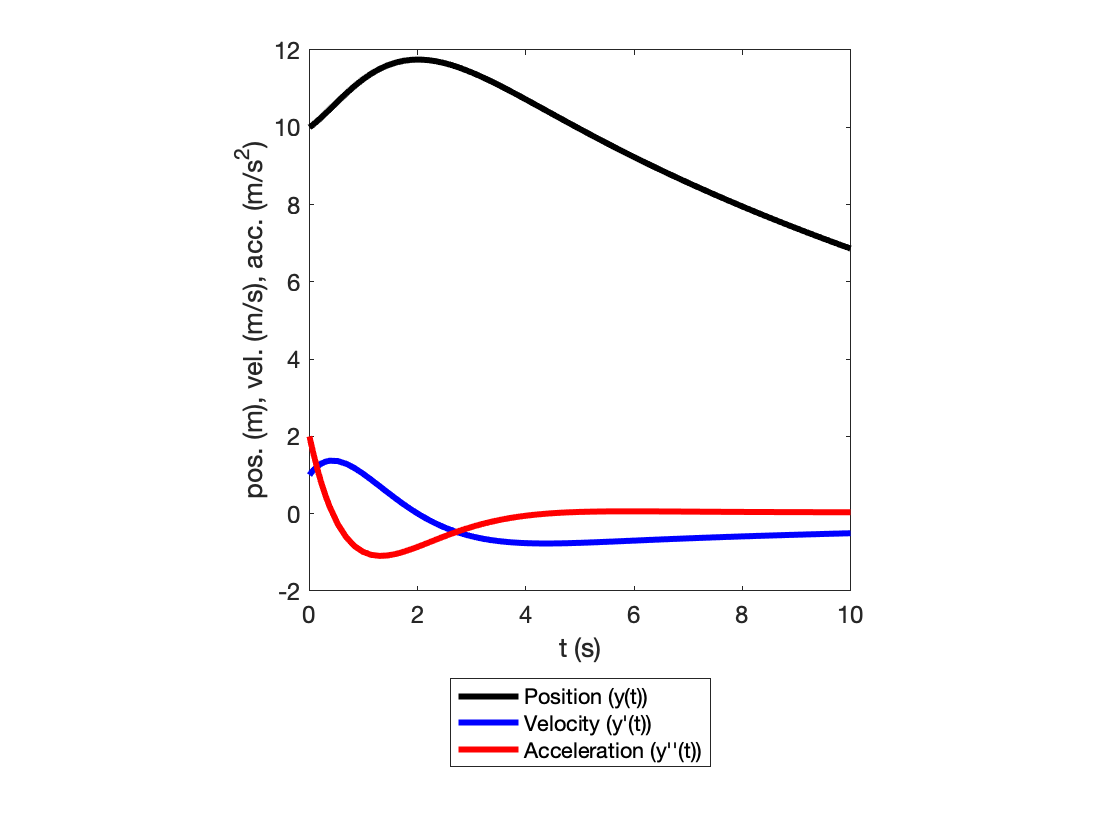

% Solve system of linear ODES
[t,x] = ode45(@thirdOrderODE,[0,10],[10,1,2]);

% Plotting system
p = plot(t,x(:,1),'k-',...
    t,x(:,2),'b-',...
    t,x(:,3),'r-');
set(p,'LineWidth',3)
set(gca,'FontSize',12)
axis square
xlabel('t (s)')
ylabel('pos. (m), vel. (m/s), acc. (m/s^2)')
legend({'Position (y(t))','Velocity (y''(t))','Acceleration (y''''(t))'},'location','southoutside')

#### Supplying additional arguments to `ode45`

The values of *p*, *q*, and *r* were defined in the ODE function - we can also supply these values when calling the solver. The function must be modified to take three additional inputs.

p = 2;
q = 1.5;
r = 0.1;

% Solve the ODE
[t,x] = ode45(@thirdOrderODE_extraInputs,[0,10],[10,1,2],[],p,q,r);

- The empty set takes the place of any options (solution tolerance) we might enforce.

- Additional inputs into the ODE function are specified at the end.

% Plotting system
p = plot(t,x(:,1),'k-',...
    t,x(:,2),'b-',...
    t,x(:,3),'r-');
set(p,'LineWidth',3)
set(gca,'FontSize',12)
axis square
xlabel('t (s)')
ylabel('pos. (m), vel. (m/s), acc. (m/s^2)')
legend({'Position (y(t))','Velocity (y''(t))','Acceleration (y''''(t))'},'location','southoutside')

#### Example problem: creating an interactive physics simulator

In Topic 6, we analytically solved for the motion of a projectile. Here, we will solve consider the differential equations representing this motion, which can be obtained from a force balance:

            
$$\begin{array}{l}
a_y =\frac{d}{\mathrm{d}t}v_y =-g\\
v_y =\frac{d}{\mathrm{d}t}y\\
a_x =0\\
v_x =\frac{d}{\mathrm{d}t}x
\end{array}$$


**Produce an interface that enables you to interactively "launch" a projectile.**

***Step 1: Plot the trajectory of the ball***

% Specify angle and velocity of the ball
th = 45;
v = 20;
vx = v*cosd(th);
vy = v*sind(th);

Writing the function to describe the ODEs:

**Important note**: even though x and y are not explicitly related, **they describe the same system and must be incorporated into ****one set of ODEs****.** If you (erroneously) call separate instances of `ode45` for each, your solution is subject to the time points the solver selects and these time points may not overlap.

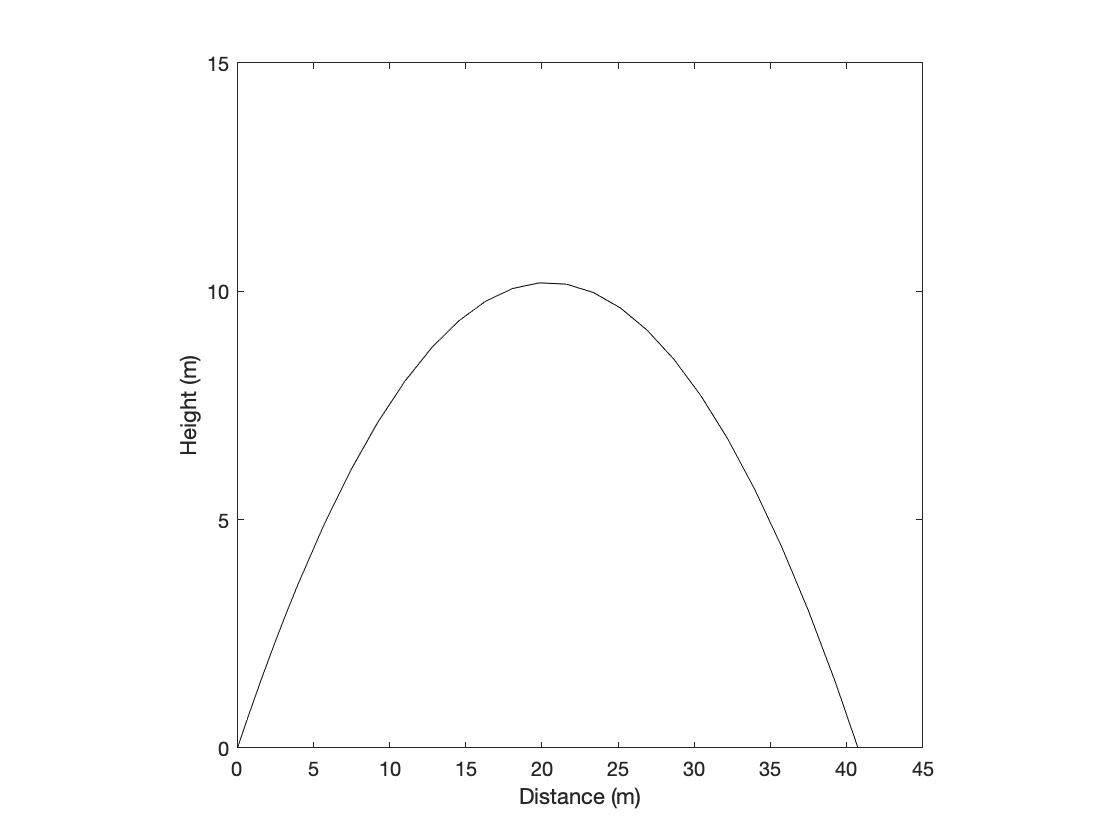

% Solving the set of ODEs. Note the additional input (x velocity)
[~,state] = ode45(@ball_2D,[0,5],[0,vy,0],[],vx);
x_ode = state(:,3); % x values
y_ode = state(:,1); % y values

figure
% Plot the height as a function of time
plot(x_ode,y_ode,'k-')
ylim([0,15])
xlabel('Distance (m)')
ylabel('Height (m)')
axis square

**Step 2: visualize trajectory of "moving ball"**

% Phyiscal parameters, as before
th = 60;
v = 15;
vx = v*cosd(th);
vy = v*sind(th);
g = 9.81;
% Estimate time to landing
t_end = 1.5*2*vy/g;

% Solve system of differential equations. Specify the time points to solve
% for
[t,state] = ode45(@ball_2D,[0:0.05:t_end],[2,vy,0],[],vx);
txy = [t,state(:,3),state(:,1)];
% Select time points corresponding to the ball not yet landing
txy = txy(txy(:,3) > 0,:);

**Note**: we explicitly specify the time points to be solved for in the input to ode45.

To produce visual motion. we will use the following algorithm:

- Solve the system of ODEs to obtain the ball's x and y position as a function of time.

- Select data points that correspond to the ball having not landed

- In each iteration, replot the ball position and add its position to the traveled points (trajectory)

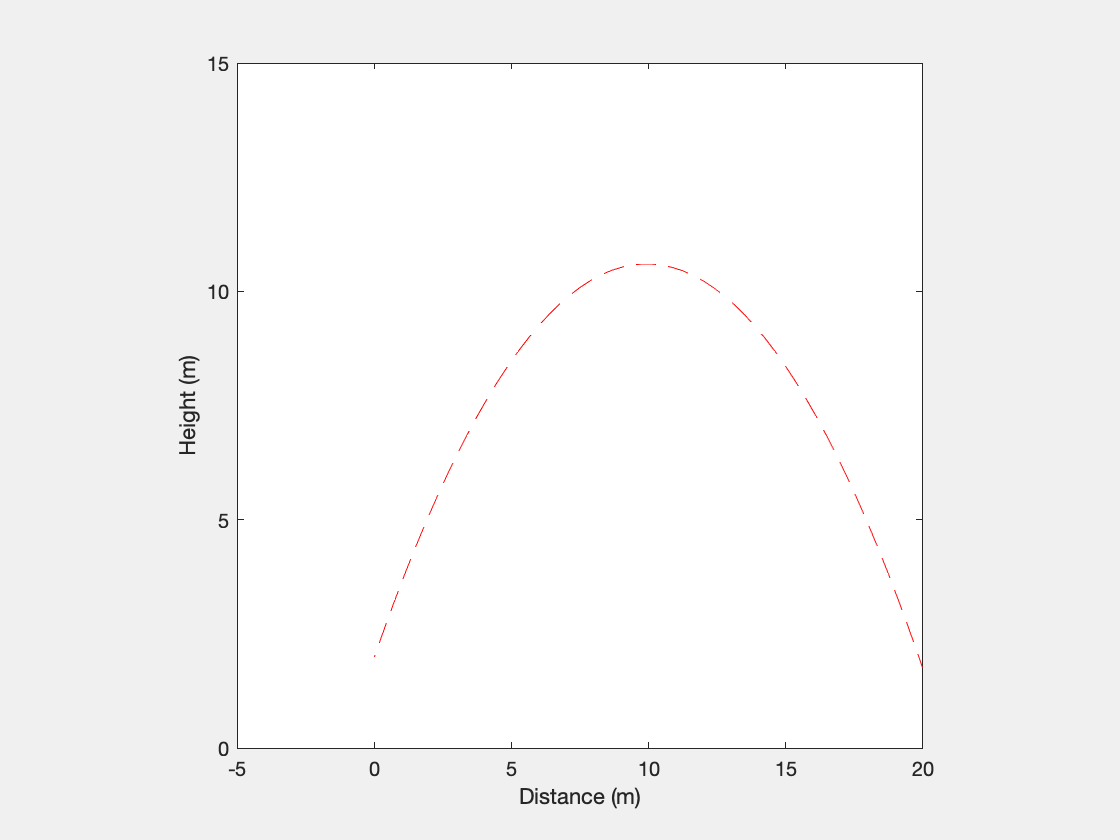

close all

% Produce figure. Specify the plots of interest and the graphical
% parameters
h1 = figure('Visible','on');
hTrajectory = plot(txy(1,2),txy(1,3),'r--');
hold on
hBall = plot(txy(1,2),txy(1,3),'ro','MarkerFaceColor','r','MarkerSize',8);
hold off
ylim([0,15])
xlim([-5,20])
xlabel('Distance (m)')
ylabel('Height (m)')
axis square

% Loop through all ball positions and update plot
for k = 2:size(txy,1)
    
    % Update plot of ball and trajectory tracer
    hBall.XData = txy(k,2);
    hBall.YData = txy(k,3);
    hTrajectory.XData(k) = txy(k,2);
    hTrajectory.YData(k) = txy(k,3);

    % Pause for specified amount of time consisted with time points solved
    % for
    pause(0.05);
    
end

**Step 3: produce an interface**

Qualitatively, we want the following:

- The location  where the user clicks will determine both the angle and initial velocity of the ball.

- Upon releasing the click, we wish to solve the ODE based on the initial parameters specified by the user click.

- Upon releasing the click, we also to visualize the trajectory of the ball.

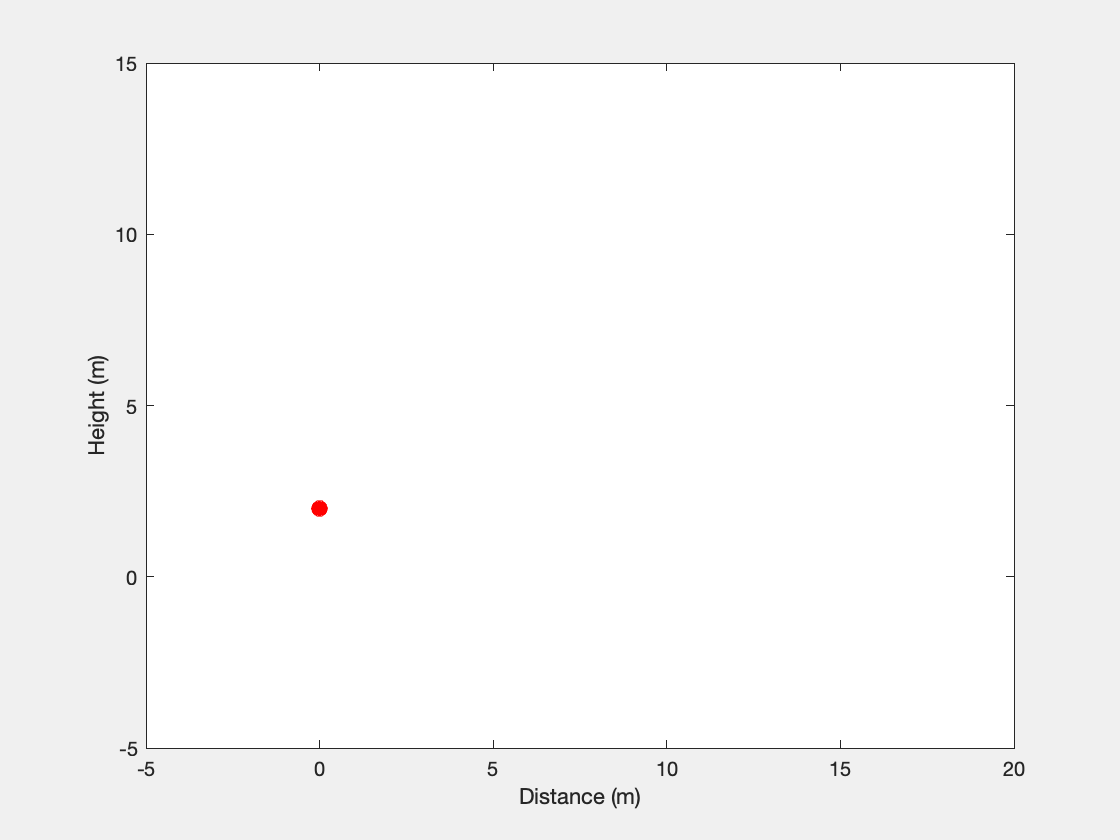

close all
% Create a figure
h1 = figure('Visible','on');

% Create and store GUI data structure
handles.h0 = 2;
guidata(h1,handles);

% Define plots for trajectory, ball, and aiming line
hTrajectory = plot(0,handles.h0,'r--');
hold on
hBall = plot(0,handles.h0,'ro','MarkerFaceColor','r','MarkerSize',8);
hAim = plot(0,handles.h0,'k-','LineWidth',2);
hold off

% Graphical parameters
ylim([-5,15])
xlim([-5,20])
xlabel('Distance (m)')
ylabel('Height (m)')


% Assign callback function for mouse click
h1.WindowButtonDownFcn = {@determineStart,hBall,hTrajectory,hAim};

% Assign callback function for mouse release
h1.WindowButtonUpFcn = {@throwBall,hBall,hTrajectory};

#### Functions for Topic 23 stored here:

**Example 1: simple ODE**

function dxdt = myODE(t,x)
    dxdt = x(1) - t^2 + 1;
end

**Example 2: coupled chemical reactions**

function dxdt = rxnEqns(t,x)
    % Here, x(1) : A
    % x(2): B
    % x(3): C
    dxdt = zeros(3,1);
    dxdt(1) = -x(1) + 2*x(2);
    dxdt(2) = x(1) - 4*x(2) + 0.5*x(3);
    dxdt(3) = 2*x(2) - 0.5*x(3);
    
end

**Example 3: third order ODE**

function dxdt = thirdOrderODE(t,x)
    % Parameters
    p = 2;
    q = 1.5;
    r = 0.1;
    
    % Note:
    % x(1) corresponds to y
    % x(2) corresponds to y'
    % x(3) corresponds to y''
    
    % Preallocating the output as a column vector
    dxdt = zeros(3,1);

    dxdt(1) = x(2);
    dxdt(2) = x(3);
    dxdt(3) = -p*x(3)-q*x(2)-r*x(1);
end

**Example 4: third order ODE, specifying additional inputs**

function dxdt = thirdOrderODE_extraInputs(t,x,p,q,r)
    dxdt = zeros(3,1);
    dxdt(1) = x(2);
    dxdt(2) = x(3);
    dxdt(3) = -p*x(3)-q*x(2)-r*x(1);
end

**Example 5: third order ODE, specifying additional inputs**

function dz = ball_2D(t,z,vx)
    % Compute the x and y position of a ball subject to gravity and
    % in a vacuum. This function is called upon by MATLAB's ODE
    % solvers. t = time (s), z = [y-position, y-velocity, x-position]
    % in units of (m, m/s, m), and dz = [y-velocity; y-acceleration;
    % x-position] in units of (m/s, m/s^2, m).
     
    dz(1,1) = z(2); % z(1): y-position
    dz(2,1) = -9.81;% z(2): y-velocity
    dz(3,1) = vx;   % z(3): x-position
end

**Example 6: mouse click function**

function determineStart(hObj,~,hBall,hTrajectory,hAim)
    % Mouse click: determine kinematics parameters
    
    % Load information associated with a data structure
    handles = guidata(hObj);
    
    % Get the current mouse location 
    pos = get(gca,'CurrentPoint');
    pos = pos(1,1:2);
    
    % Specify the inital x and y positions
    hBall.XData = 0;
    hBall.YData = handles.h0;
    hTrajectory.XData = 0;
    hTrajectory.YData = handles.h0;

    % Calculate difference in x and y values
    dy = abs(pos(2) - handles.h0);
    dx = abs(pos(1) - 0);
    % Calculate angle to throw
    handles.th = atan2d(dy,dx);
    
    % Define initial velocity to be proportional to distance away clicked
    handles.v = 3*sqrt(dy^2 + dx^2);

    % Create a line showing aim
    hAim.XData(2) = pos(1);
    hAim.YData(2) = pos(2);
    
    % Store object data
    guidata(hObj,handles);
    
end

**Example 7: mouse release function**

function throwBall(hObj,~,hBall,hTrajectory)
    % Mouse release: calculate and visualize trajectory
    
    % Load GUI data
    handles = guidata(hObj);
    th = handles.th;
    h0 = handles.h0;
    v = handles.v;
    
    % Calculate parameters
    vx = v*cosd(th);
    vy = v*sind(th);
    g = 9.81;
    t_end = 2*2*vy/g;
    
    % Solve system of differential equations. Specify the time points to solve
    % for
    [t,state] = ode45(@ball_2D,[0:0.05:t_end],[2,vy,0],[],vx);
    txy = [t,state(:,3),state(:,1)];
    % Select time points corresponding to the ball not yet landing
    txy = txy(txy(:,3) > 0,:);

    
    % Loop through all ball positions and update plot
    for k = 2:size(txy,1)
        
        % Update plot of ball and trajectory tracer
        hBall.XData = txy(k,2);
        hBall.YData = txy(k,3);
        hTrajectory.XData(k) = txy(k,2);
        hTrajectory.YData(k) = txy(k,3);
    
        % Pause for specified amount of time consisted with time points solved
        % for
        pause(0.05);
        
    end

end